# Mohammad Amanlou     810100084

# Engineering Mthematics CA2  

## Part1: Solving the heat equation

In this part, we want to solve the heat equation for a rod 2 meters long, the initial temperature is The bar is 0°C and the temperature at its end is 50°C.

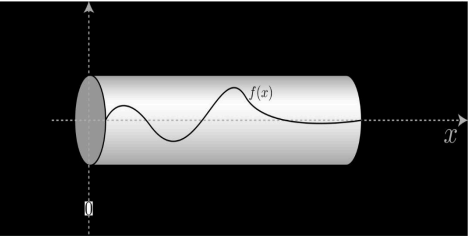

The equation along with its boundary conditions are presented as follows.

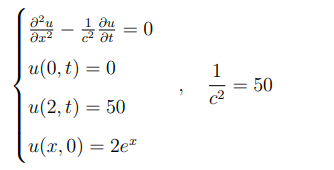

To solve this case, we can easily reach the required equation by inserting the following items:

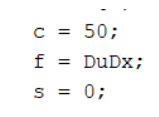

### Part1.4: Solving the equation

x = linspace(0, 2, 200);  % Discretize the spatial domain from 0 to 2 with 200 points
t = linspace(0, 10, 201); % Discretize the time domain from 0 to 10 with 201 points

sol = pdepe(0, @Equation, @Init, @BC, x, t);  % Solve the PDE using pdepe

### Part 1.5: 

Show the temperature of the bar at times 10 5, 0, = t in a graph and present your analysis.

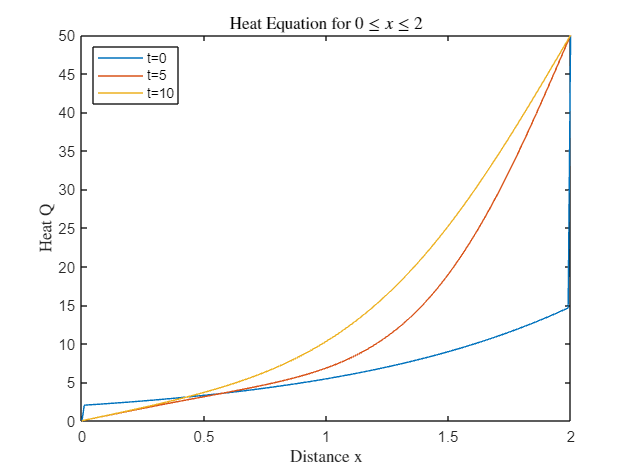

% Plot the solution at different times
plot(x, sol(1,:))       % Plot for t = 0
hold on
plot(x, sol(101,:))     % Plot for t = 5
plot(x, sol(201,:))     % Plot for t = 10
hold off
legend('t=0', 't=5', 't=10', 'Location', 'northwest')  % Add legend
title('Heat Equation for $0 \le x \le 2$', 'interpreter', 'latex')  % Title of the plot
xlabel('Distance x', 'interpreter', 'latex')  % X-axis label
ylabel('Heat Q', 'interpreter', 'latex')      % Y-axis label

As expected, over time the effect of the initial condition disappears and the graph is more under  The effect will be the form of the equation and the boundary conditions. That is, at t=0, the difference between the heat (temperature) of the two sides  It is not much, but with the passage of time, the difference in heat (temperature) becomes more and more.

According to the resulting graph, with the passage of time and the increase of t, the graph tends from the initial conditions to the boundary conditions

Now, with the help of imagesc(), colormap() commands, two-dimensional graph of temperature changes  We draw and observe and analyze over space and time:

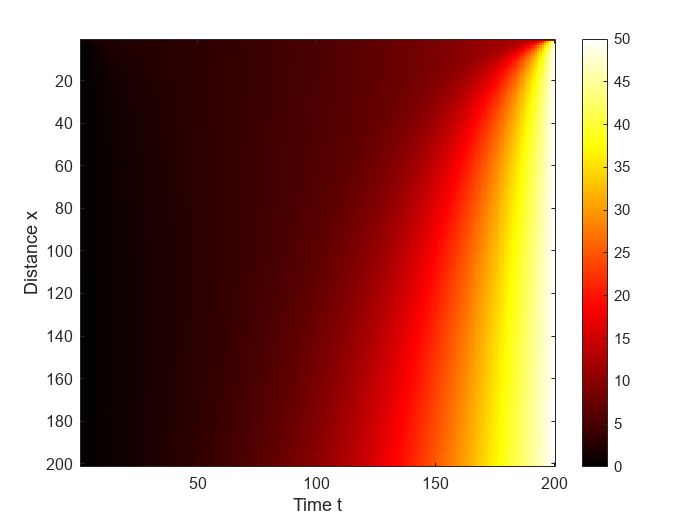

imagesc(sol)  % Display the solution as an image
colormap hot  % Apply hot colormap
xlabel('Time t')  % X-axis label
ylabel('Distance x')  % Y-axis label
colorbar  % Add colorbar

According to the resulting graph, with the passage of time and the increase of t, the heat spreads in the rod and the temperature of the rod increases. (The yellow color, which indicates a higher temperature, increases at the bottom of the diagram.)

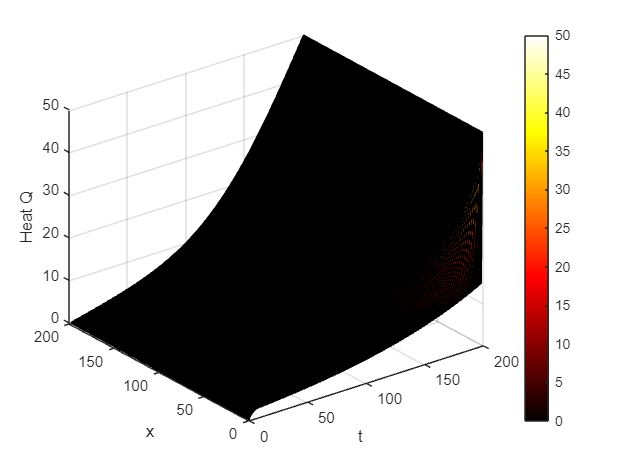

surf(sol)  % Display the solution as a 3D surface plot
xlabel("t")  % X-axis label
ylabel("x")  % Y-axis label
zlabel('Heat Q')  % Z-axis label
colorbar  % Add colorbar

Finally, we repeat all the work for new intervals:

The only difference is that we take longer steps and this makes us feel a little relaxed  The graphs are reduced and basically, the accuracy of the graphs has decreased.

% Solve the PDE again with different spatial and time discretization
x = linspace(0, 2, 100);  % Discretize the spatial domain from 0 to 2 with 100 points
t = linspace(0, 10, 101); % Discretize the time domain from 0 to 10 with 101 points

sol = pdepe(0, @Equation, @Init, @BC, x, t);  % Solve the PDE using pdepe

Divide x and t into 100 and 101 parts, respectively, then repeat the previous request

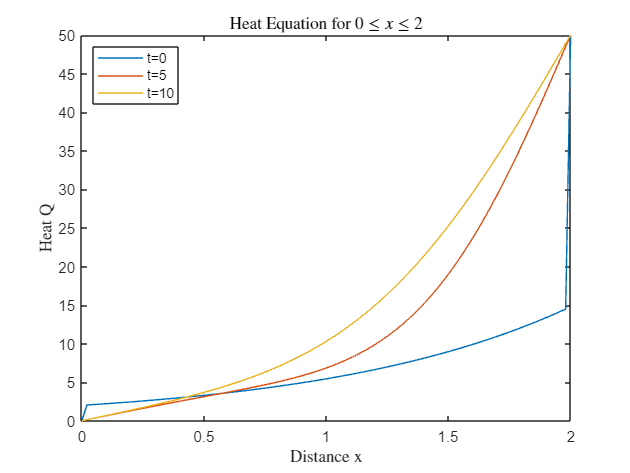

% Plot the solution at different times
plot(x, sol(1,:))       % Plot for t = 0
hold on
plot(x, sol(51,:))      % Plot for t = 5
plot(x, sol(101,:))     % Plot for t = 10
hold off
legend('t=0', 't=5', 't=10', 'Location', 'northwest')  % Add legend
title('Heat Equation for $0 \le x \le 2$', 'interpreter', 'latex')  % Title of the plot
xlabel('Distance x', 'interpreter', 'latex')  % X-axis label
ylabel('Heat Q', 'interpreter', 'latex')      % Y-axis label

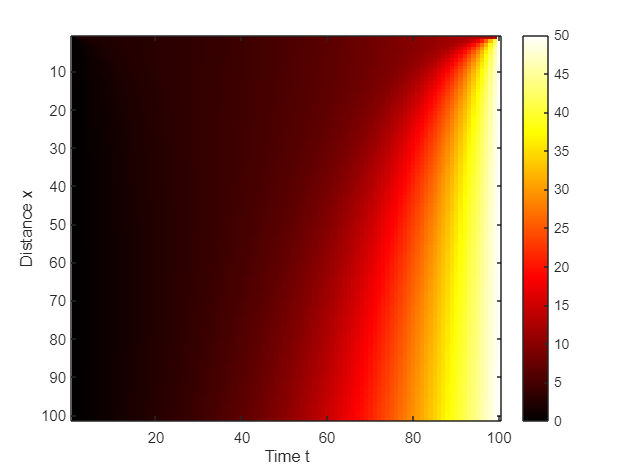

imagesc(sol)  % Display the solution as an image
colormap hot  % Apply hot colormap
xlabel('Time t')  % X-axis label
ylabel('Distance x')  % Y-axis label
colorbar  % Add colorbar

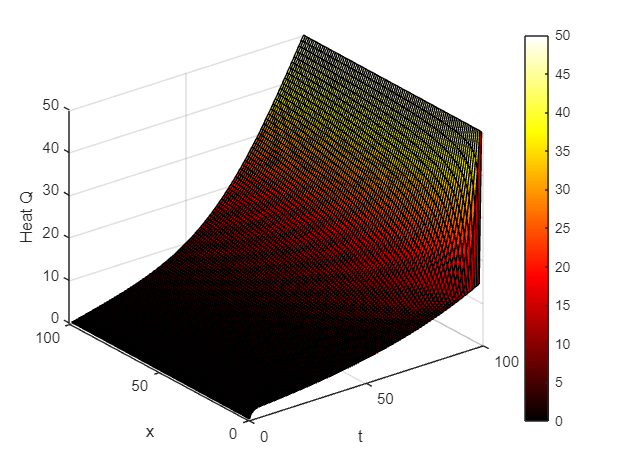

surf(sol)  % Display the solution as a 3D surface plot
xlabel("t")  % X-axis label
ylabel("x")  % Y-axis label
zlabel('Heat Q')  % Z-axis label
colorbar  % Add colorbar

## Part2 : Solving the Helmholtz equation

In this part, we want to solve and check the Helmholtz equation in the Modeler PDE environment. The general form of the equation is  is below

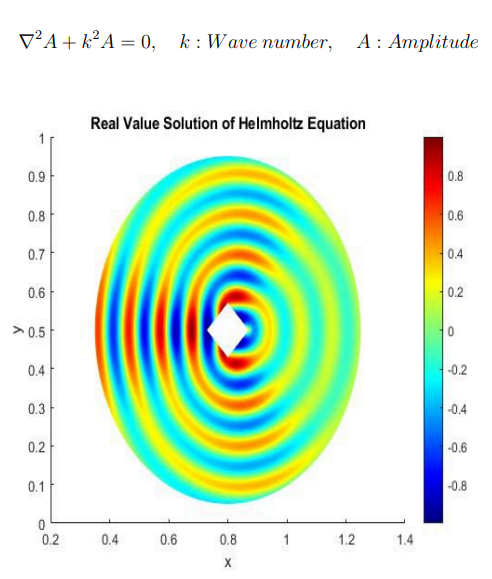

### Part2.1: Steps to solve the equation

#### Methods of solving the Helmholtz equation: 

1. The method of separating variables: this method to solve the equation in simple domains with boundary conditions  It is used appropriately. First, it is assumed that the solution is the product of several functions  is univariate and then by separating the variables, several ordinary differential equations to  is achieved 

2. Spectral method: Spectral methods (this method includes Fourier transformation or similar transformations  To convert the differential equation to frequency domain. In this domain, the equation becomes  It becomes an algebraic equation that is easier to solve. 

3. Numerical method: from numerical methods such as Finite Difference Finite Element Method (for solving the Helmholtz equation  It is used in more complex domains.

All in all, First, we open PDE Modeler by typing pdeModeler in CMD of MATLAB software. 

Then  We enter the range of x and y axes [1.5 0.1] and [1 0] respectively. 

Then we draw a circle with a radius of 0.45 and center (0.8 0.5). We also set the working mode to Generic Scalar.

Then we set the boundary conditions from the Neumann condition with   −60i = q    and 0 =  g 

Then we determine the initial conditions of the mesh and finally solve the equation.

#### Boundary conditions: 

The boundary conditions of the Helmholtz equation can be as follows: 

1. Dirichlet Boundary Conditions (the value of AAA function in the boundaries  The domain is clear  

2. Neumann Boundary Conditions (the value of the normal derivative of AAA function It is defined within the boundaries of the domain  

3. Mixed Boundary Conditions (combination of Dirichlet and Neumann conditions  at different domain boundaries. 

4. Radiation conditions: Boundary Radiation Conditions (for issues in open spaces  (as in radio waves), radiation conditions are used that include wave attenuation  is infinite

#### Steps to solve the equation

First, start PDE Modeler by writing pdeModeler in CMD of the software  I opened MATLAB:

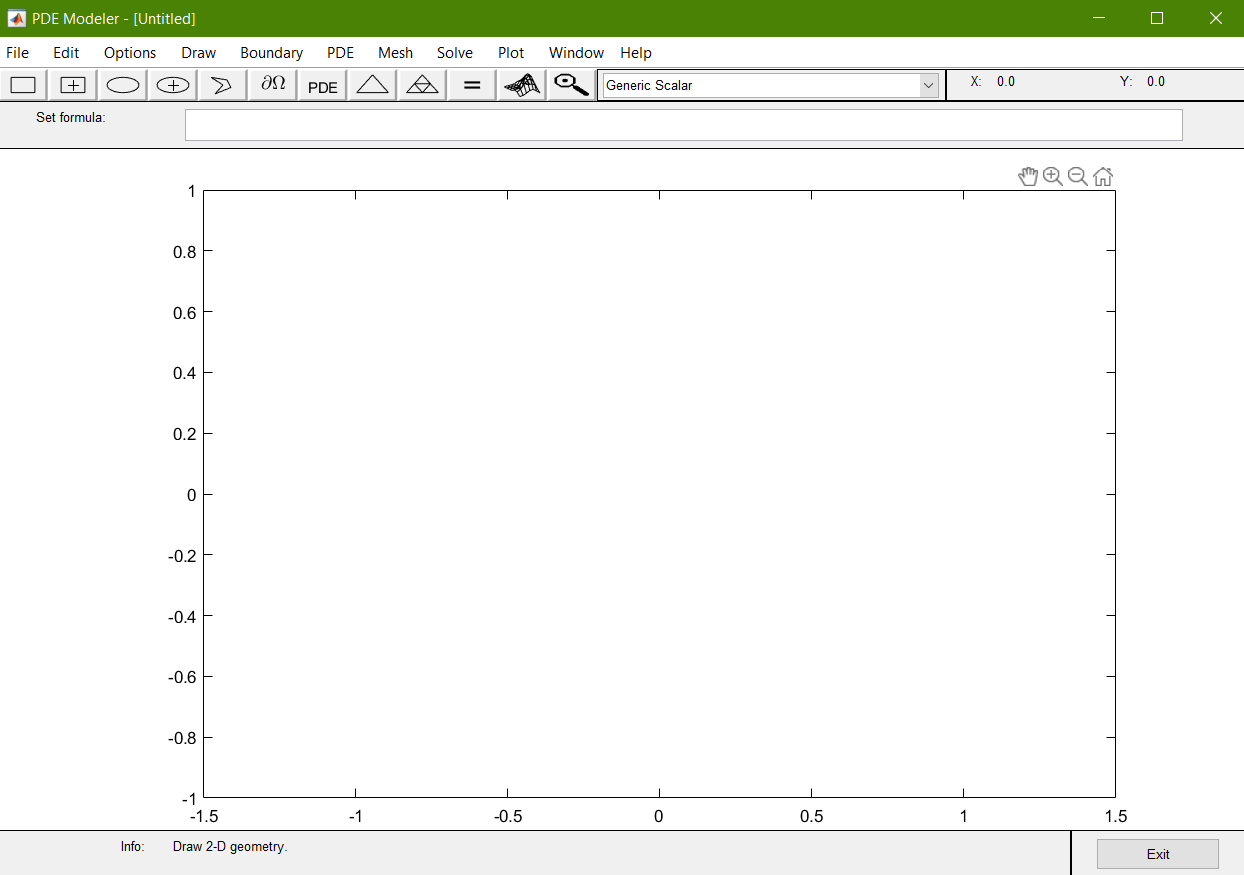

I considered the range of x and y axes [1.5 0.1] and [1 0], respectively.( to do  For this, I referred to the Options-Axes limits section ):

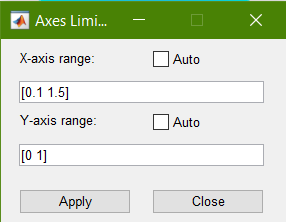

I drew a circle with a radius of 0.45 and a center (0.5 0.8)

#### 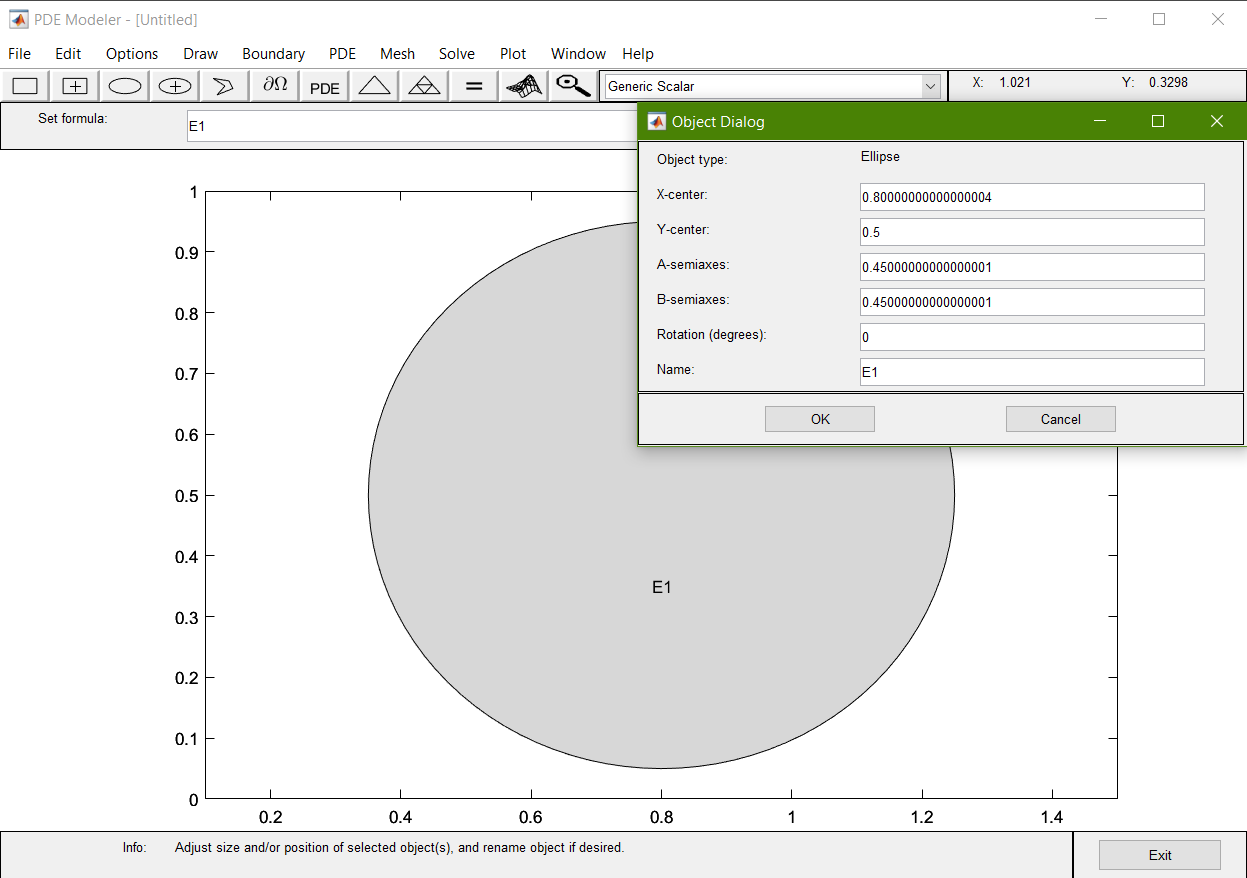

I set the work mode to Generic Scalar by referring to the Application mode section

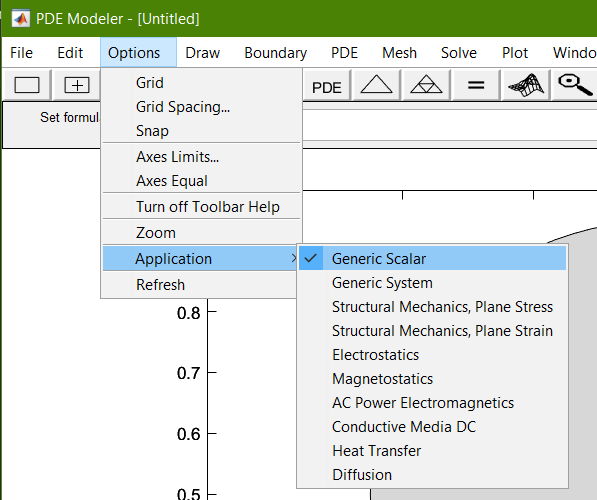

Boundary conditions by referring to the section -Specify Boundary Conditions I specified Boundary. I noticed that the boundary condition of the Neumann condition with  I use q = −60i and g = 0

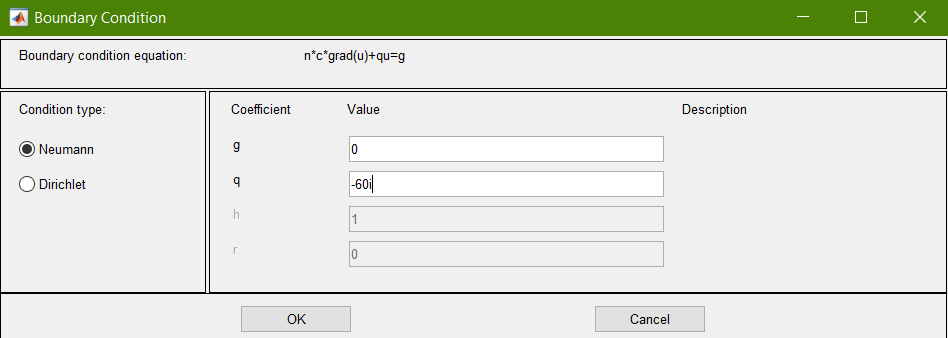

By referring to the Mesh-Initialize Mesh section, I determined the initial conditions of the mesh

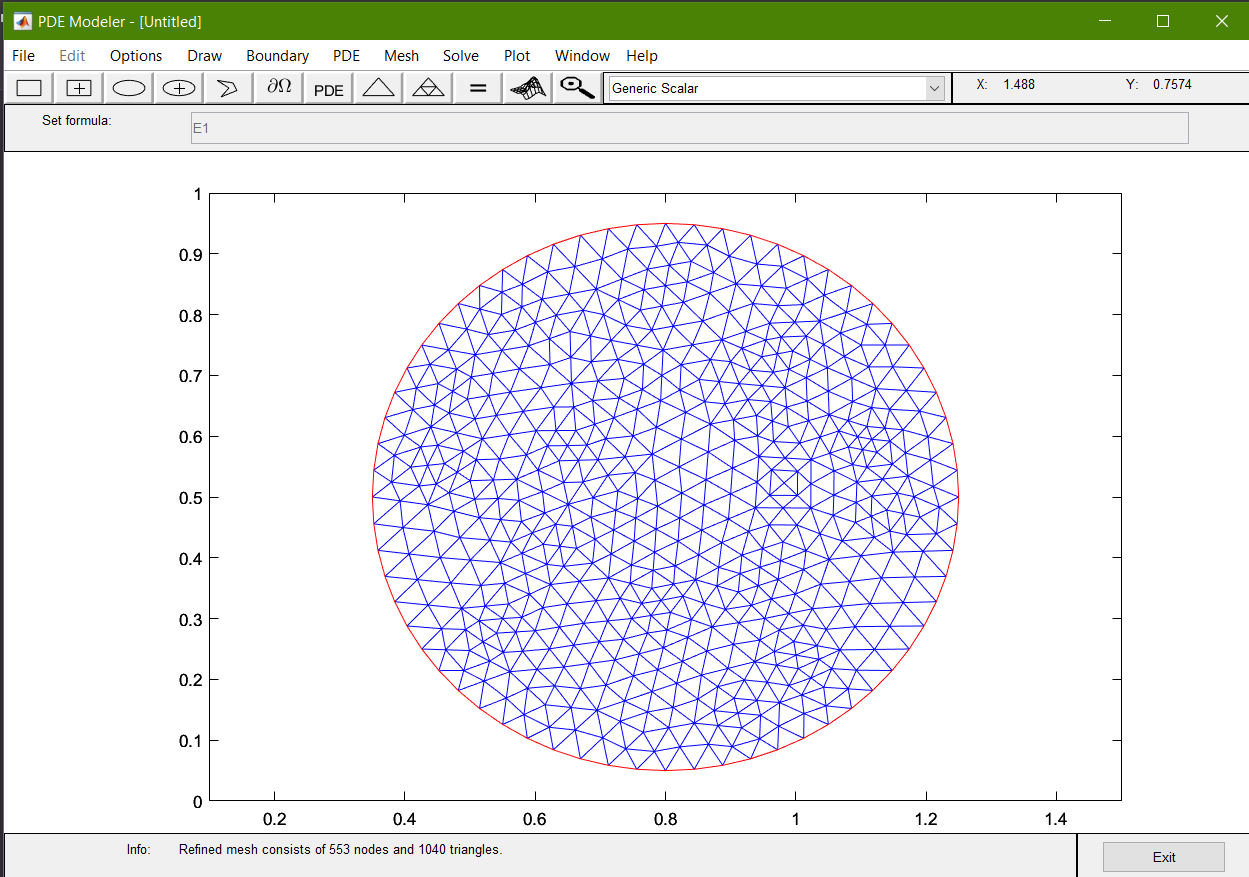

Now I solved the equation and drew the waveform

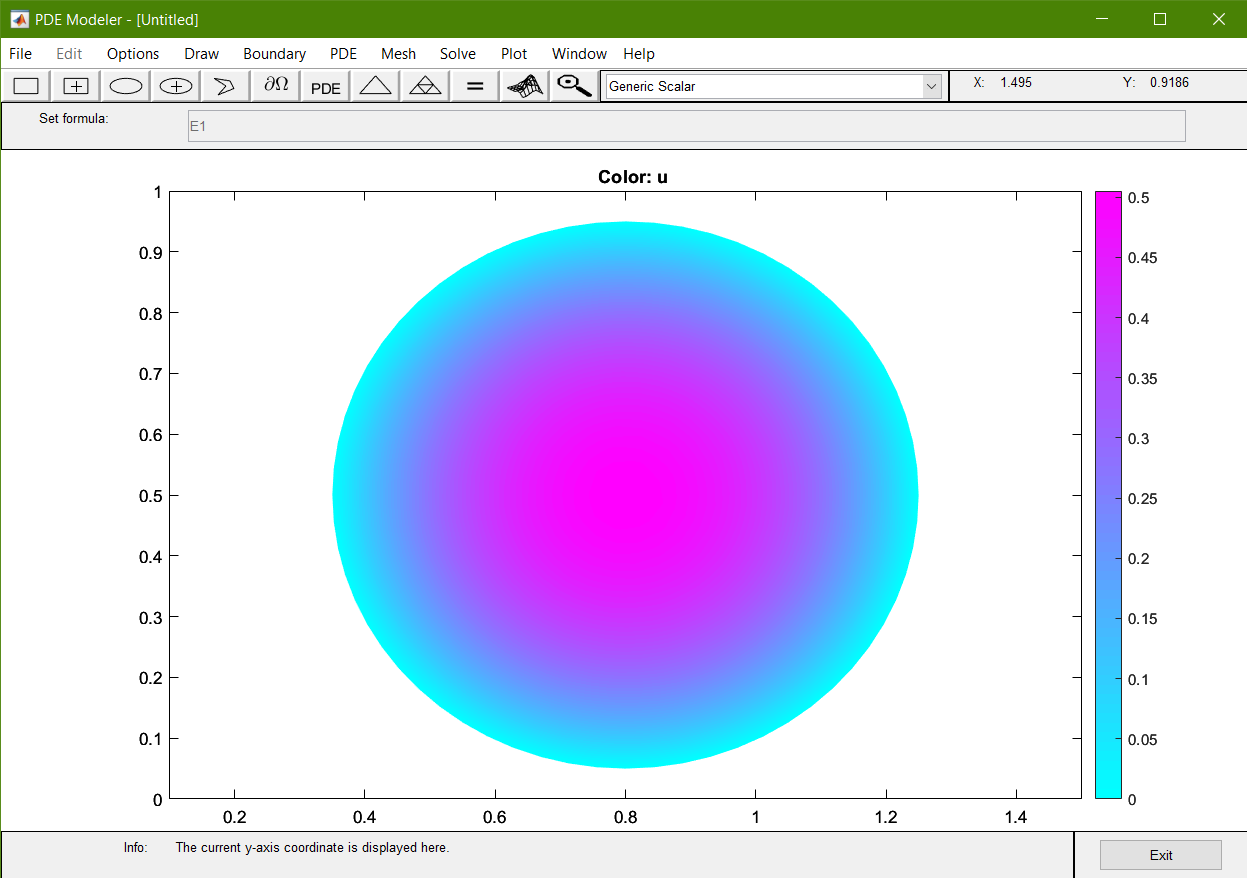

And with other colors:

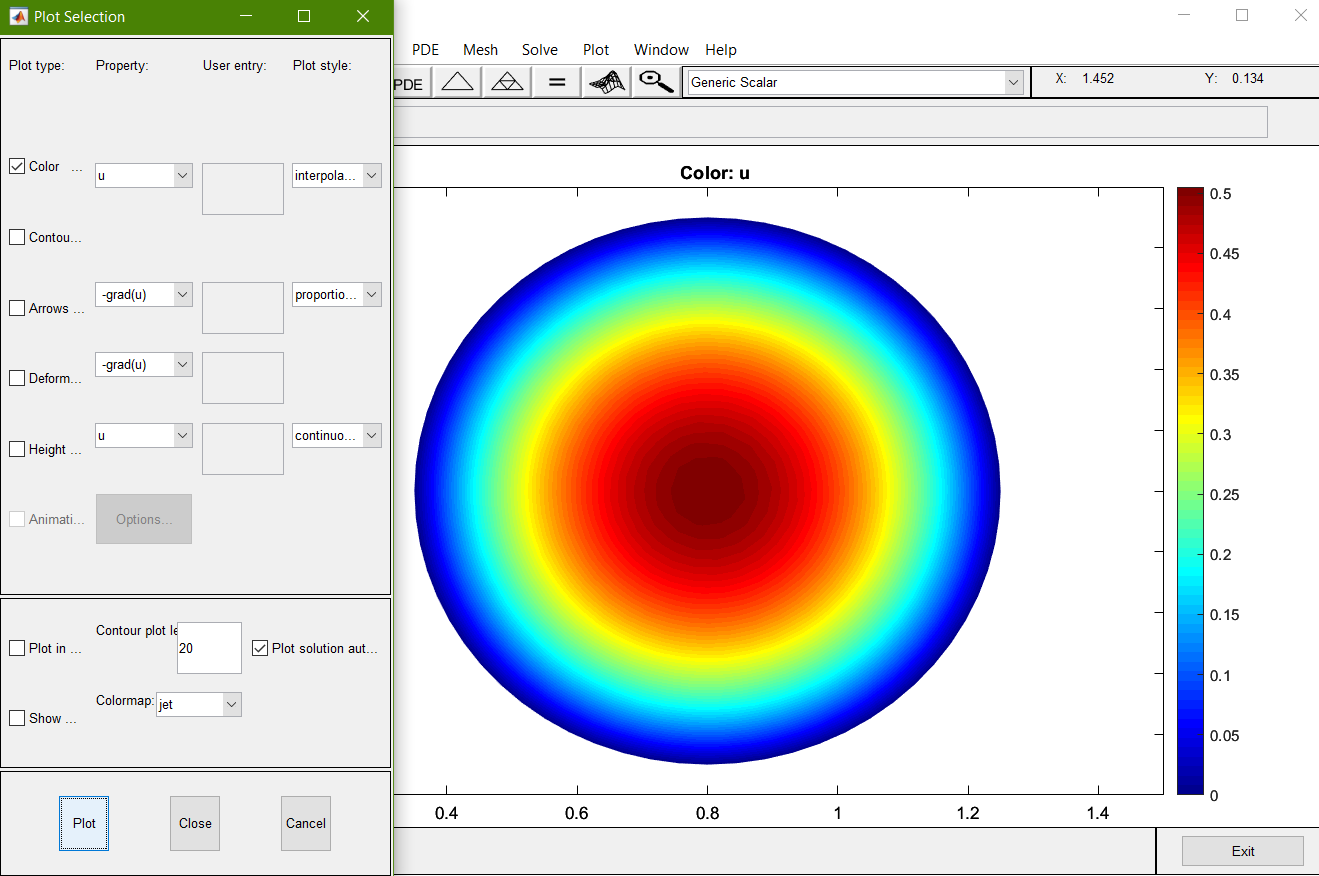

#### Description of the final shape: 

• Circle drawn: This circle defines the solution region of the Helmholtz equation. Newman boundary conditions are applied on this circle.

 • Boundary conditions: Newman's boundary conditions mean that the derivative of un with respect to the normal of the circular surface is constant.  These conditions usually indicate wave reflection from the boundary. 

• Answer: Different colors in the picture represent different values ��of u. As can be seen,  The distribution of colors is circular and concentric, which indicates spherical waves that propagate outward from the center of the circle. 

• Imaginary part u: The displayed warning indicates that the imaginary part u has been ignored. This issue is usually due to solving the equation as a complex number, which can represent attenuated or transmitted waves.

changes in setting in show:

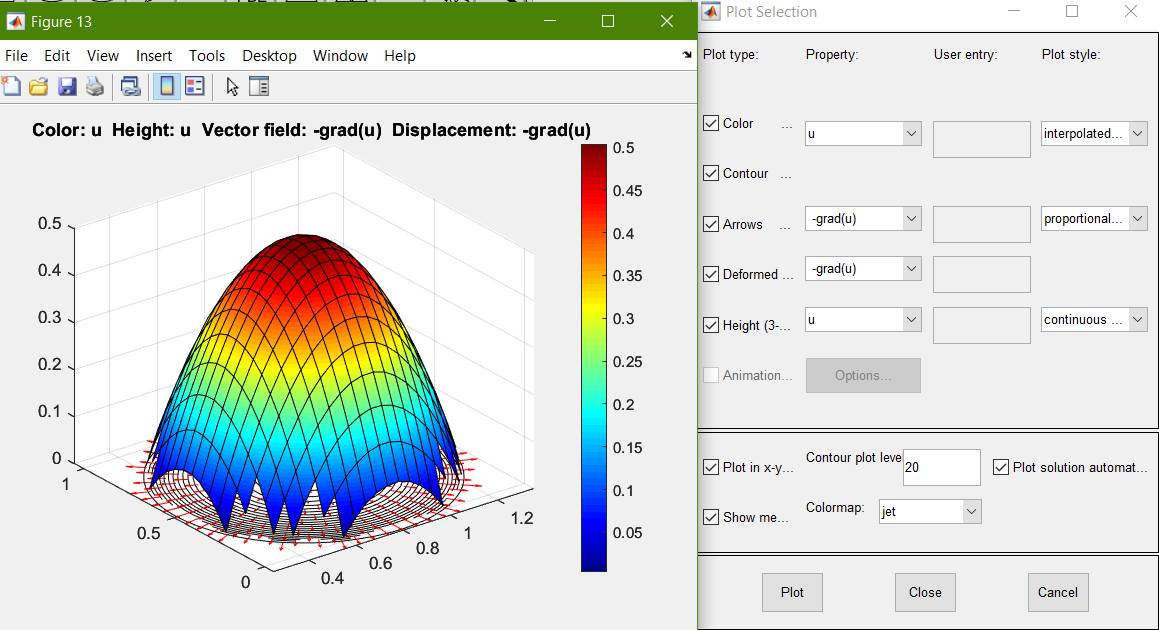

### Explain:

This diagram justifies sound propagation, as we can see in the figure, near the source of sounf, the intensity is a lot and when we move away, the intensity decreases.

The Helmholtz equation is a partial differential equation often used in physics and engineering to describe wave propagation or other scalar fields. The colorful circular pattern in the image likely represents the intensity of a wave or another scalar field at different points in a two-dimensional space. Each color represents a specific value or range of the field, with a color bar on the right side providing a reference for interpreting these colors and their corresponding values.

The colors range from blue at the outer edge to red at the center, indicating varying values of the parameter. This could represent, for example, a wave that is most intense at the center and decreases in intensity towards the edges.

### Part2.2: Deriving the Helmholtz equation from the wave equation (Extra Bonus):

The Helmholtz equation is a time-independent wave equation, which is also known as the frequency domain wave equation, and one of its applications is to calculate the movement of seismic waves in the earth. We consider the following wave equation and use the variable separation method to solve it.

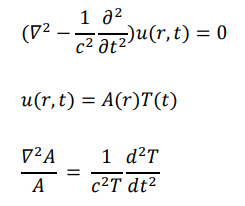

To establish this equation, both sides must be equal to a constant value. So we get two separate equations, one for A(r) and one for T(t)

By rearranging the A(r) equation, we get the Helmholtz equation, which is independent of time.

In the resulting equation, k is the wave number and A is the amplitude.

 As a result, any wave equation with homogeneous initial conditions can be converted into a Helmholtz equation due to separability. 

To solve the Helmholtz equation, we use the variable separation method for the simplicity of the solution. 

The solution of the Helmholtz equation in Cartesian coordinates will be as follows:

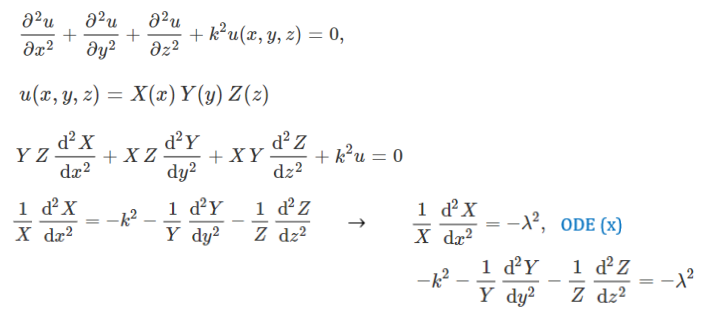

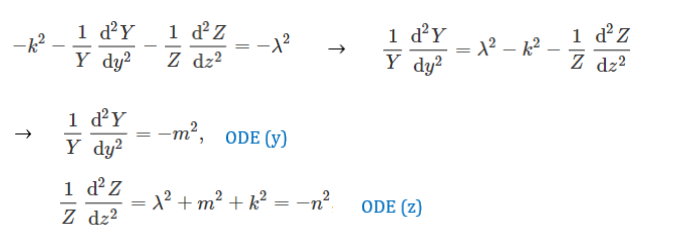

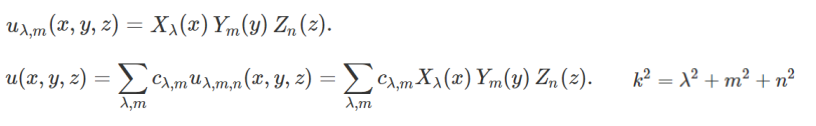

In the obtained answer, the boundary conditions of the problem should be used to calculate the coefficient C_y,m

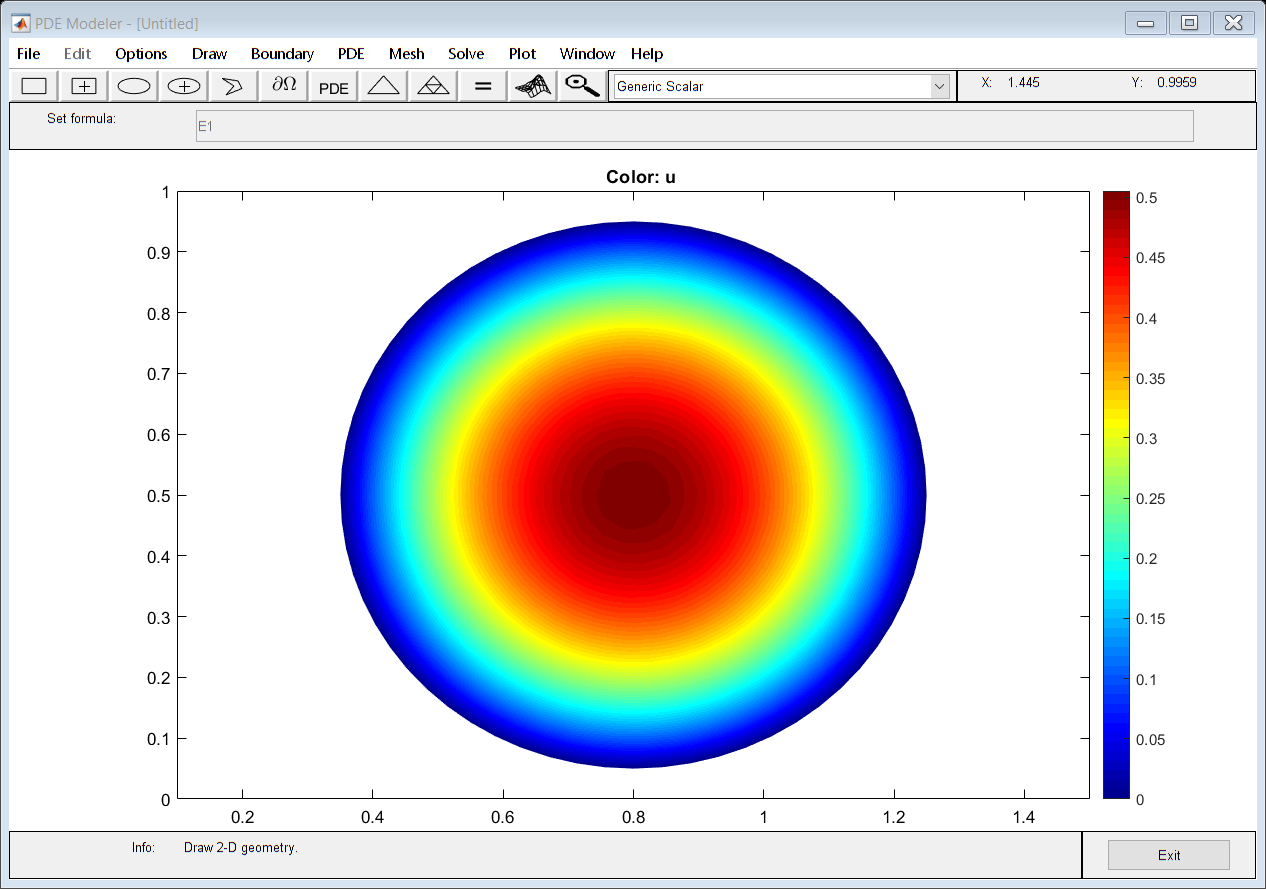

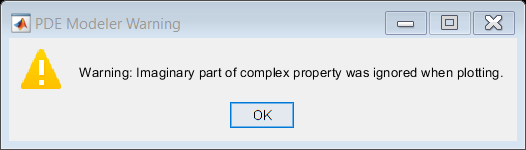

run Q2_2d.m

### **Part 1.1: **The general form of the equation in MATLAB

function [c, f, s] = Equation(x, t, u, DuDx)
    c = 50;    % Coefficient for the time derivative term, scaled by 50
    f = DuDx;  % Flux term representing the spatial derivative of u
    s = 0;     % Source term is zero (no additional source)
end

### Part1.2: preliminary conditions

function value = Init(x)
    value = 2 .* exp(x);  % Initial condition: u(x, 0) = 2 * exp(x)
end

### Part1.3: Boundary conditions

The general form of boundary conditions in MATLAB is as follows.

function [pl, ql, pr, qr] = BC(xl, ul, xr, ur, t)
    pl = ul;     % Left boundary condition at x = 0
    ql = 0;      % Coefficient for the left boundary
    pr = ur - 50; % Right boundary condition at x = 2
    qr = 0;      % Coefficient for the right boundary
end